% ===============================================================
% SVD + KNN Digit Recognition (MNIST)
% ===============================================================

clc;
clear;
close all;

%% 1. Load MNIST dataset
disp('Loading MNIST dataset...');

Loading MNIST dataset...



[XTrain, YTrain] = digitTrain4DArrayData;
[XTest, YTest] = digitTest4DArrayData;

%% 2. Convert images to 2D (Flatten 28x28 → 784)

XTrain = reshape(XTrain,28*28,[])';
XTest  = reshape(XTest,28*28,[])';

%% 3. Convert labels to numeric
YTrain = double(categorical(YTrain));
YTest  = double(categorical(YTest));

%% 4. Normalize pixel values
XTrain = double(XTrain)/255;
XTest  = double(XTest)/255;

%% 5. Mean Centering

meanImage = mean(XTrain,1);

XTrain_centered = XTrain - meanImage;
XTest_centered  = XTest - meanImage;

%% 6. Apply SVD

disp('Performing SVD...');

Performing SVD...



[U,S,V] = svd(XTrain_centered,'econ');

%% 7. Select top K features

k = 50;

V_k = V(:,1:k);

%% 8. Project data into reduced space

XTrain_proj = XTrain_centered * V_k;
XTest_proj  = XTest_centered  * V_k;

%% 9. Train KNN classifier

disp('Training KNN classifier...');

Training KNN classifier...



Mdl = fitcknn(XTrain_proj,YTrain,'NumNeighbors',1);

%% 10. Predict Test Data

Y_pred = predict(Mdl,XTest_proj);

%% 11. Calculate Accuracy

accuracy = mean(Y_pred == YTest)*100;

fprintf('Test Accuracy: %.2f%%\n',accuracy);

Test Accuracy: 99.90%


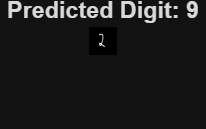


%% ===============================================================
%% 12. Custom Image Prediction
%% ===============================================================

function predict_custom_image(image_path,meanImage,V_k,Mdl)

% Read image
img = imread(image_path);

% Convert to grayscale
if size(img,3) == 3
    img = rgb2gray(img);
end

% Resize to 28x28
img_resized = imresize(img,[28 28]);

% Invert colors if background is white
if mean(img_resized(:)) > 127
    img_resized = 255 - img_resized;
end

% Normalize
img_flat = double(reshape(img_resized,1,[]))/255;

% Mean center
img_centered = img_flat - meanImage;

% SVD Projection
img_proj = img_centered * V_k;

% Predict digit
pred_label = predict(Mdl,img_proj);

% Display image
figure;
imshow(img_resized,[]);
title(['Predicted Digit: ',num2str(pred_label)],'FontSize',14);

end

%% Example usage

predict_custom_image("C:\Users\HP\OneDrive\Desktop\OneDrive\Documents\Hand written digit recognition\number2.png.png",meanImage,V_k,Mdl);